# Tutorial 9: Interference Free Workspace Analysis (Part 1: Define Obstacle(s))

This tutorial will show how to define a polynomial represented obstacle for the interference-free workspace analysis.

Currently, you need to provide the implicit polynomial surfaces with respect to (x,y,z) and the boundary curves

It is suggested to 

To define a closed obstacle, you need the following information 

- The implicit function(s) of the surface(s) (Stored as a Cell)

- The x,y,z boundaries of the surface(s)  (Stored as a Cell)

- The surface direction: which side of the surface you used.  (Stored as a Array)

- The boundary equations (if any) (Stored as a Cell)

- The boundary variable range (Stored as a Cell)

- The connectivity information of the surfaces and boundary (Stored as a Matrix)

Here is an example of ball obstacle, since the ball itself is closed obstacle, you can let the boundary equations empty:

clear; close all; clc;

Ball_Center = [0.5;0.35;0.5];
Ball_Radius = 0.17;

F_i{1} = @(x,y,z) (x - Ball_Center(1)).^2 + (y - Ball_Center(2)).^2 + (z - Ball_Center(3)).^2 - Ball_Radius^2;
XYZ_Range{1} = [Ball_Center(1)-Ball_Radius,...
    Ball_Center(1)+Ball_Radius,...
    Ball_Center(2)-Ball_Radius,...
    Ball_Center(2)+Ball_Radius,...
    Ball_Center(3)-Ball_Radius,...
    Ball_Center(3)+Ball_Radius];

F_i_Side(1) = -1;

Boundary_Parametric_Equation  = [];
Parametric_Variable_Range     = [];
Boundary_Surface_Connectivity = [];

Ball_Obstacle  = CreateObstacleElement(F_i,XYZ_Range,F_i_Side,Boundary_Parametric_Equation,Parametric_Variable_Range,Boundary_Surface_Connectivity);

Creating the obstacle(s), please plot the obstacle for ensurance of the surfaces and boundary equations
Only considering the exterior of the obstacles.


Now you can plot the obstacle to ensure it is correct. You have control in:

- PlotMethod   : 1(default) is the triangulation plot; 2 is the implicit plot; Use 1 for obstacle constructed by multiple surfaces.

- PlotEdge       : 0(default). Set it to be 1 to plot the boundaries if they exist

- Meshdensity : The surface finess for implicit plot method;  (Default: 20)

- FaceAlpha    : Transparence of the surface (Default: 1)

- Color             : Surface color (Default: interp)

- EdgeColor    : Edge color  (Default: black)

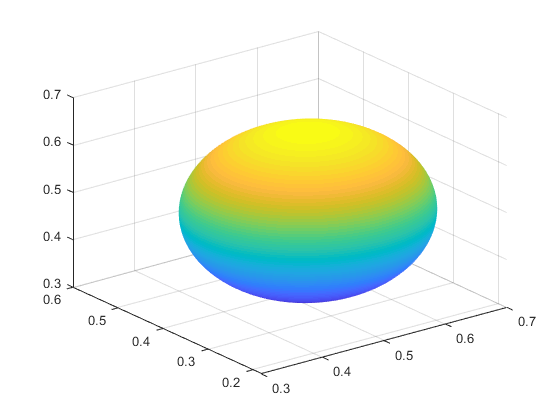

figure
Ball_Obstacle.plotObstacle('PlotMethod',1,'Color','interp','EdgeColor','none','PlotEdge',1);

If your obstacle is not hollowed like a donut, you can neglect the interriors to speed up the computation.

Ball_Obstacle  = CreateObstacleElement(F_i,XYZ_Range,F_i_Side,Boundary_Parametric_Equation,Parametric_Variable_Range,Boundary_Surface_Connectivity,'NeglectInterior',1);

Creating the obstacle(s), please plot the obstacle for ensurance of the surfaces and boundary equations
Only considering the exterior of the obstacles.


If you found the interference analysis is incorrect, it might be caused by the computation tolorence of the obstacles. You can increase or decrease the tolerance by:

Ball_Obstacle  = CreateObstacleElement(F_i,XYZ_Range,F_i_Side,Boundary_Parametric_Equation,Parametric_Variable_Range,Boundary_Surface_Connectivity,'ObstacleTol',0.0035);

Creating the obstacle(s), please plot the obstacle for ensurance of the surfaces and boundary equations
Only considering the exterior of the obstacles.


Next, a list of obstacle examples are shown

-  Cubic obstacle

clear; clc;
figure
F_i{1} =@(x,y,z) (120*(x-0.5)).^2 + (120*(y-0.5)).^2 - (1 + 15*z).*(10*(z-1)).^2;
XYZ_Range{1} = [0.36315,0.63685,0.36315,0.63685,0,1];
F_i_Side(1) = -1;

Boundary_Parametric_Equation  = [];
Parametric_Variable_Range     = [];
Boundary_Surface_Connectivity = [];

Cubic_Obstacle  = CreateObstacleElement(F_i,XYZ_Range,F_i_Side,Boundary_Parametric_Equation,Parametric_Variable_Range,Boundary_Surface_Connectivity);

Creating the obstacle(s), please plot the obstacle for ensurance of the surfaces and boundary equations
Only considering the exterior of the obstacles.


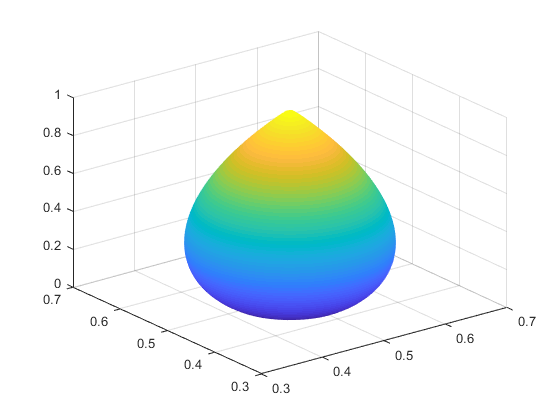

Cubic_Obstacle.plotObstacle('PlotMethod',1,'Color','interp','EdgeColor','none','PlotEdge',1);

- Box obstacle

clear; clc;
figure;

F_i{1} =@(x,y,z) 1*(x-0) + 0*(y-0) + 0*(z-0) ;
XYZ_Range{1} = [-0.0001 0.0001 0.25 0.55 0.25 0.55];
F_i_Side(1) = 1;
F_i{2} =@(x,y,z) 1*(x-0.3) + 0*(y-0) + 0*(z-0) ;
XYZ_Range{2} = [0.29999 0.30001 0.25 0.55 0.25 0.55];
F_i_Side(2) = -1;

F_i{3} =@(x,y,z) 0*(x-0) + 1*(y-0.25) + 0*(z-0) ;
XYZ_Range{3} = [0 0.3 0.24999 0.25001 0.25 0.55];
F_i_Side(3) = 1;
F_i{4} =@(x,y,z) 0*(x-0) + 1*(y-0.55) + 0*(z-0) ;
XYZ_Range{4} = [0 0.3 0.54999 0.55001 0.25 0.55];
F_i_Side(4) = -1;

F_i{5} =@(x,y,z) 0*(x-0) + 0*(y-0) + 1*(z-0.25) ;
XYZ_Range{5} = [0 0.3 0.25 0.55 0.24999 0.2501];
F_i_Side(5) = 1;
F_i{6} =@(x,y,z) 0*(x-0) + 0*(y-0) + 1*(z-0.55) ;
XYZ_Range{6} = [0 0.3 0.25 0.55 0.54999 0.55001];
F_i_Side(6) = -1;


Boundary_Parametric_Equation{1} =@(t) [0; 0.25; 0.25 + 0.3*t];
Boundary_Parametric_Equation{2} =@(t) [0; 0.55; 0.25 + 0.3*t];
Boundary_Parametric_Equation{3} =@(t) [0; 0.3*t+0.25; 0.25];
Boundary_Parametric_Equation{4} =@(t) [0; 0.3*t+0.25; 0.55];

Boundary_Parametric_Equation{5} =@(t) [0.3; 0.25; 0.25 + 0.3*t];
Boundary_Parametric_Equation{6} =@(t) [0.3; 0.55; 0.25 + 0.3*t];
Boundary_Parametric_Equation{7} =@(t) [0.3; 0.3*t+0.25; 0.25];
Boundary_Parametric_Equation{8} =@(t) [0.3; 0.3*t+0.25; 0.55];

Boundary_Parametric_Equation{9} =@(t) [0+0.3*t; 0.25; 0.25];
Boundary_Parametric_Equation{10} =@(t) [0+0.3*t; 0.25; 0.55];
Boundary_Parametric_Equation{11} =@(t) [0.0+0.3*t; 0.55; 0.55];
Boundary_Parametric_Equation{12} =@(t) [0.0+0.3*t; 0.55; 0.25];

Parametric_Variable_Range = repmat({[0,1]},12,1);

Boundary_Surface_Connectivity = [   1  1  3;
    2  1  4;
    3  1  5;
    4  1  6;
    5  2  3;
    6  2  4;
    7  2  5;
    8  2  6;
    9  3  5;
    10 3  6;
    11 4  6;
    12 4  5];
Box_Obstacle  = CreateObstacleElement(F_i,XYZ_Range,F_i_Side,Boundary_Parametric_Equation,Parametric_Variable_Range,Boundary_Surface_Connectivity);

Creating the obstacle(s), please plot the obstacle for ensurance of the surfaces and boundary equations
Only considering the exterior of the obstacles.


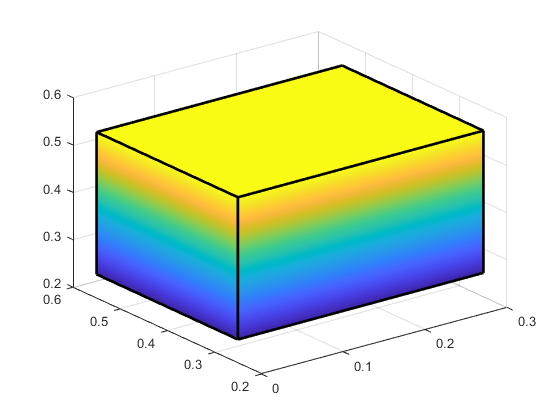

Box_Obstacle.plotObstacle('PlotMethod',1,'Color','interp','EdgeColor','none','PlotEdge',1);

- Goursat obstacle

clear; clc;
figure;

a = 0;
b = 0;
c = -0.0005;
F_i{1} =@(x,y,z) (x -0.15).^4 + (y - 0.4).^4 + (z - 0.4).^4 + a*((x - 0.15).^2 +(y - 0.4).^2 +(z-0.075).^2) + c;
XYZ_Range{1} = [0 0.3 0.25 0.55 0.25 0.55];
F_i_Side(1) = -1;

Boundary_Parametric_Equation  = [];
Parametric_Variable_Range     = [];
Boundary_Surface_Connectivity = [];

Goursat_Obstacle  = CreateObstacleElement(F_i,XYZ_Range,F_i_Side,Boundary_Parametric_Equation,Parametric_Variable_Range,Boundary_Surface_Connectivity);

Creating the obstacle(s), please plot the obstacle for ensurance of the surfaces and boundary equations
Only considering the exterior of the obstacles.


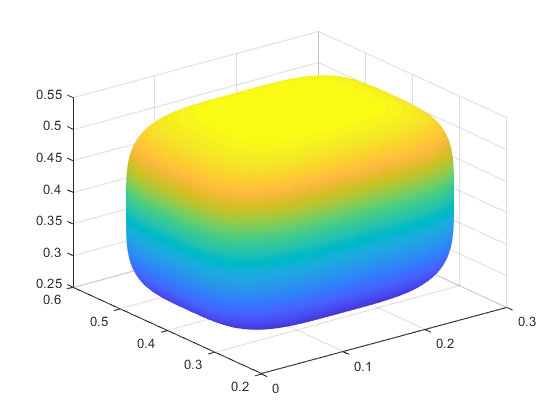

Goursat_Obstacle.plotObstacle('PlotMethod',1,'Color','interp','EdgeColor','none','PlotEdge',1);

- Donut

clear; clc;
figure;

R = 0.2;
r = R/4;
F_i{1} =@(x,y,z) ((x-0.3).^2 + ((y-0.4)).^2 + (z - 0.4).^2 + R.^2 - r.^2).^2 - 4*R.^2.*((x-0.3).^2 + ((y-0.4)).^2);
F_i_Side(1) = -1;
Boundary_Parametric_Equation = [];
XYZ_Range{1} = [0.05 0.55 0.15 0.65 0.35 0.45];

Boundary_Parametric_Equation  = [];
Parametric_Variable_Range     = [];
Boundary_Surface_Connectivity = [];


Donut_Obstacle  = CreateObstacleElement(F_i,XYZ_Range,F_i_Side,Boundary_Parametric_Equation,Parametric_Variable_Range,Boundary_Surface_Connectivity,'NeglectInterior',0);

Creating the obstacle(s), please plot the obstacle for ensurance of the surfaces and boundary equations
Considering the interior of the obstacles. Slower computation might be occured...


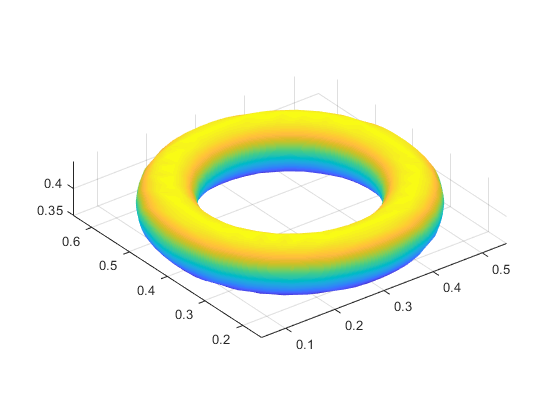

Donut_Obstacle.plotObstacle('PlotMethod',2,'Color','interp','EdgeColor','none','PlotEdge',0);
axis equal

Finally, for complex obstacle, it is suggested to had multiple closed surface sets such as

clear; clc;
figure; hold on;
% Tree part 1
F_i{1} = @(x,y,z) (x-0.5).^2 + (y-0.5).^2 - 0.09^2; %cylinder
XYZ_Range{1} = [0.5-0.09 0.5+0.09 0.5-0.09 0.5+0.09 0 0.2];
F_i_Side(1) = -1;

F_i{2} = @(x,y,z) z - 0.2;
XYZ_Range{2} = [0.5-0.09 0.5+0.09 0.5-0.09 0.5+0.09 0.2 0.2];
F_i_Side(2) = -1;

x =@(u,a,xc,sx) -(sx*a.*(1 - u.^2)/(1+u.^2)) + xc; %
y =@(u,b,yc,sy) sy*2*b.*u/(1+u.^2) + yc;
z =@(u,c,zc,sz) sz*zc;

Boundary_Parametric_Equation{1} = @(t) [x(t,0.09,0.5,1);y(t,0.09,0.5,1);z(t,0.09,0.2,1)];
Parametric_Variable_Range{1} = [-1,1];

x =@(u,a,xc,sx) (sx*a.*(1 - u.^2)/(1+u.^2)) + xc; %
y =@(u,b,yc,sy) sy*2*b.*u/(1+u.^2) + yc;
z =@(u,c,zc,sz) sz*zc;

Boundary_Parametric_Equation{2} = @(t) [x(t,0.09,0.5,1);y(t,0.09,0.5,1);z(t,0.09,0.2,1)];
Parametric_Variable_Range{2} = [-1,1];

Boundary_Surface_Connectivity = [1,1,2;2,1,2];

Tree_Obstacle(1)  = CreateObstacleElement(F_i,XYZ_Range,F_i_Side,Boundary_Parametric_Equation,Parametric_Variable_Range,Boundary_Surface_Connectivity);

Creating the obstacle(s), please plot the obstacle for ensurance of the surfaces and boundary equations
Considering the interior of the obstacles. Slower computation might be occured...


Tree_Obstacle(1).plotObstacle('PlotMethod',1,'Color','interp','EdgeColor','none','PlotEdge',1);

% Tree part 2

F_i{1} = @(x,y,z) (x-0.5).^2/0.3 + (y-0.5).^2 /0.3 - ((0.85*z) - 0.45).^2;%lower
XYZ_Range{1} = [0.3466 0.6534 0.34 0.6534 0.20 0.4];
F_i_Side(1) = -1;

F_i{2} = @(x,y,z) z - 0.2;
XYZ_Range{2} = [0.3466 0.6534 0.34 0.6534 0.2 0.2];
F_i_Side(2) = 1;

F_i{3} = @(x,y,z) z - 0.4;
XYZ_Range{3} = [0.4397 0.56025 0.4397 0.56025 0.4 0.4];
F_i_Side(3) = -1;

x =@(u,a,xc,sx) -(sx*a.*(1 - u.^2)/(1+u.^2)) + xc; %
y =@(u,b,yc,sy) sy*2*b.*u/(1+u.^2) + yc;
z =@(u,c,zc,sz) sz*zc;

Boundary_Parametric_Equation{1} = @(t) [x(t,0.1534,0.5,1);y(t,0.1534,0.5,1);z(t,0.1534,0.2,1)];
Parametric_Variable_Range{1} = [-1,1];
Boundary_Parametric_Equation{3} = @(t) [x(t,0.0603,0.5,1);y(t,0.0603,0.5,1);z(t,0.0603,0.4,1)];
Parametric_Variable_Range{3} = [-1,1];

x =@(u,a,xc,sx) (sx*a.*(1 - u.^2)/(1+u.^2)) + xc; %
y =@(u,b,yc,sy) sy*2*b.*u/(1+u.^2) + yc;
z =@(u,c,zc,sz) sz*zc;

Boundary_Parametric_Equation{2} = @(t) [x(t,0.1534,0.5,1);y(t,0.1534,0.5,1);z(t,0.1534,0.2,1)];
Parametric_Variable_Range{2} = [-1,1];
Boundary_Parametric_Equation{4} = @(t) [x(t,0.0603,0.5,1);y(t,0.0603,0.5,1);z(t,0.0603,0.4,1)];
Parametric_Variable_Range{4} = [-1,1];

Boundary_Surface_Connectivity = [1,1,2;2,1,2;3,1,3;4,1,3];

Tree_Obstacle(2)  = CreateObstacleElement(F_i,XYZ_Range,F_i_Side,Boundary_Parametric_Equation,Parametric_Variable_Range,Boundary_Surface_Connectivity);

Creating the obstacle(s), please plot the obstacle for ensurance of the surfaces and boundary equations
Considering the interior of the obstacles. Slower computation might be occured...


Tree_Obstacle(2).plotObstacle('PlotMethod',1,'Color','interp','EdgeColor','none','PlotEdge',1);

% Tree part 3
F_i{1} = @(x,y,z) (x-0.5).^2/0.2 + (y-0.5).^2 /0.2 - ((0.85*z) - 0.6).^2;
XYZ_Range{1} = [0.384 0.616 0.384 0.616 0.4 0.65];
F_i_Side(1) = -1;

F_i{2} = @(x,y,z) z - 0.4;
XYZ_Range{2} = [0.384 0.616 0.384 0.616 0.4 0.4];
F_i_Side(2) = 1;

F_i{3} = @(x,y,z) z - 0.65;
XYZ_Range{3} = [0.384 0.616 0.384 0.616 0.65 0.65];
F_i_Side(3) = -1;

x =@(u,a,xc,sx) -(sx*a.*(1 - u.^2)/(1+u.^2)) + xc; %
y =@(u,b,yc,sy) sy*2*b.*u/(1+u.^2) + yc;
z =@(u,c,zc,sz) sz*zc;

Boundary_Parametric_Equation{1} = @(t) [x(t,0.116,0.5,1);y(t,0.116,0.5,1);z(t,0.116,0.4,1)];
Parametric_Variable_Range{1} = [-1,1];

x =@(u,a,xc,sx) (sx*a.*(1 - u.^2)/(1+u.^2)) + xc; %
y =@(u,b,yc,sy) sy*2*b.*u/(1+u.^2) + yc;
z =@(u,c,zc,sz) sz*zc;

Boundary_Parametric_Equation{2} = @(t) [x(t,0.116,0.5,1);y(t,0.116,0.5,1);z(t,0.116,0.4,1)];
Parametric_Variable_Range{2} = [-1,1];


x =@(u,a,xc,sx) -(sx*a.*(1 - u.^2)/(1+u.^2)) + xc; %
y =@(u,b,yc,sy) sy*2*b.*u/(1+u.^2) + yc;
z =@(u,c,zc,sz) sz*zc;

Boundary_Parametric_Equation{3} = @(t) [x(t,0.021242,0.5,1);y(t,0.021242,0.5,1);z(t,0.116,0.65,1)];
Parametric_Variable_Range{3} = [-1,1];

x =@(u,a,xc,sx) (sx*a.*(1 - u.^2)/(1+u.^2)) + xc; %
y =@(u,b,yc,sy) sy*2*b.*u/(1+u.^2) + yc;
z =@(u,c,zc,sz) sz*zc;

Boundary_Parametric_Equation{4} = @(t) [x(t,0.021242,0.5,1);y(t,0.021242,0.5,1);z(t,0.116,0.65,1)];
Parametric_Variable_Range{4} = [-1,1];

Boundary_Surface_Connectivity = [1,1,2;2,1,2;3,1,3;4,1,3];
Tree_Obstacle(3)  = CreateObstacleElement(F_i,XYZ_Range,F_i_Side,Boundary_Parametric_Equation,Parametric_Variable_Range,Boundary_Surface_Connectivity);

Creating the obstacle(s), please plot the obstacle for ensurance of the surfaces and boundary equations
Considering the interior of the obstacles. Slower computation might be occured...


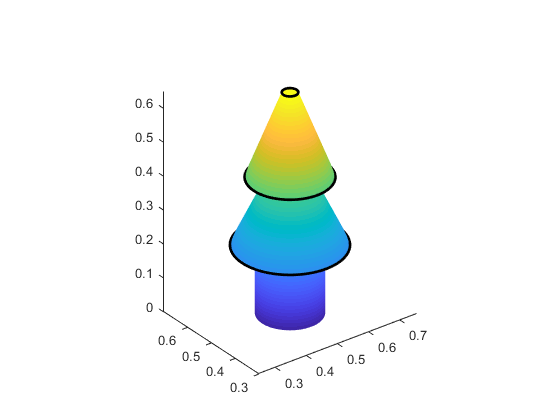

Tree_Obstacle(3).plotObstacle('PlotMethod',1,'Color','interp','EdgeColor','none','PlotEdge',1);
axis equal
view(3)